# matGasFlow

matGasFlow is a tool to calculate the steady-state gas flow in gas distribution and transport networks.

## Setup

Use `setup_matGasFlow()` to add all necessary folders to the path.

clc
setup_matGasFlow()

## Aufgabe 1 - Versorgung von Lummerland über das Festland

Die Insel Lummerland soll bei 'b' (x:70, y:120) über eine 230 km lange Pipeline vom Festland an der Stelle 'a' (x:310, y:120) mit H-Gas versorgt werden. Die Pipeline ist für eine maximale Transportmenge von 500 MW auszulegen. Der Druck am Einspeisepunkt 'a' liegt bei 50 barg. Am Entnahmepunkt darf der Druck 30 barg nicht unterschreiten. Das Wasser sowie das Erdreich am Festland und auf den Inseln hat das ganze Jahr über eine konstante Temperatur von 10°C. Die Innenwand der Pipeline hat eine Rauhigkeit von 50 µm.

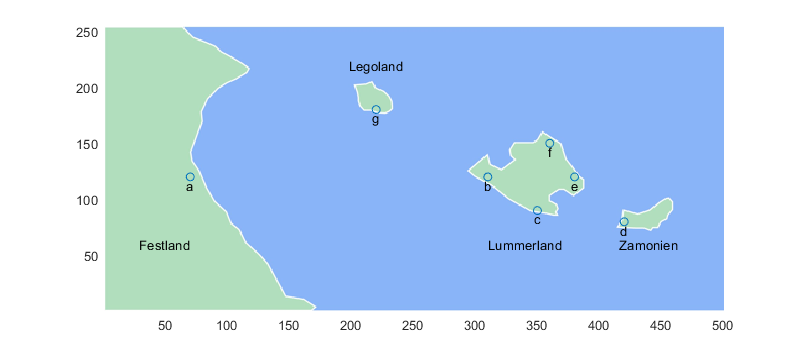

show_Lummerland;

### Aufgabe 1.a) Netzmodell

Wähle für den Durchmesser der Pipeline zunächst 1000 mm. Modelliere das Gasnetz (GN) als MATLAB struct und nutzte anschließend die Funktion 'check_and_int_GN', um die Angaben im Netzmodell zu überprüfen und um notwendige Zusatzinformationen (Temporary Data) zu erzeugen, die für die anschließende Gasflussberechnung notwendig sind. Hier sind ein paar erste Codezeilen.

- Schau dir die Error und Warning Messages an und vervollständige den Quellcode so, dass weder Error noch Warning Messages ausgegeben werden.

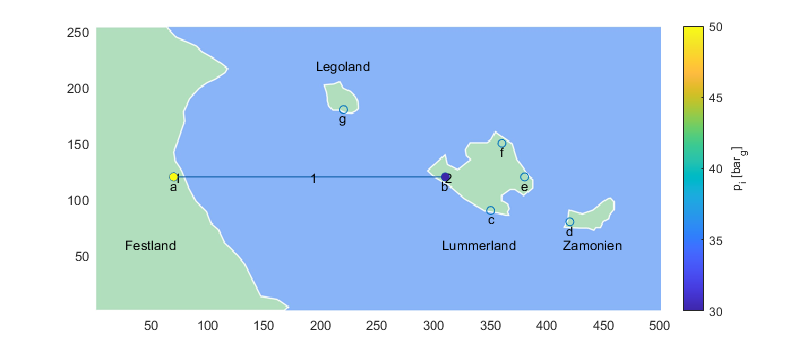

GN          = [];

bus_ID      = [1; 2];
p_i__barg   = [50; 30];
P_th_i__MW  = [-500; 500];

x_coord     = [70; 310];
y_coord     = [120; 120];
GN.bus      = table(bus_ID, p_i__barg, P_th_i__MW, x_coord, y_coord);

pipe_ID     = 1;
from_bus_ID = 1;
to_bus_ID   = 2;
L_ij        = 230000;
D_ij        = 1;
k_ij        = 5e-5;
GN.pipe     = table(pipe_ID, from_bus_ID, to_bus_ID, L_ij, D_ij, k_ij);
GN.name     = 'Lummerland';
GN.T_env    = 283.15;
GN.gasMix   = 'H_Gas_Mix';
GN          = check_and_init_GN(GN);
h           = show_Lummerland;
plot_GN_area(GN,h,[],true);


% RESULT 1a
GN1a = GN;

### Aufgabe 1.b) Ermittlung des Durchmessers

Ermittle den Durchmesser der Pipeline so, dass der Druckverlust bei Spitzenlast maximal bei 10 bar liegt. So soll die Leitung auch für zukünftige Erhöhungen der Spitzenlast "ausreichend" groß dimensioniert sein.

- Nutze dazu den folgenden Code und ergänze ihn bei '???'. 

- Schau dir die Warning-Messages an. Was bedeuten sie?

GN          = GN1a;
D_ij        = 0.1:0.01:1;
p_out__barg = NaN(size(D_ij));
for ii = 1:length(D_ij)
    GN.pipe.D_ij = D_ij(ii);
    [GN,success] = rungf(GN);
    if success
        p_out__barg(ii) = GN.bus.p_i__barg(2);
    end
end

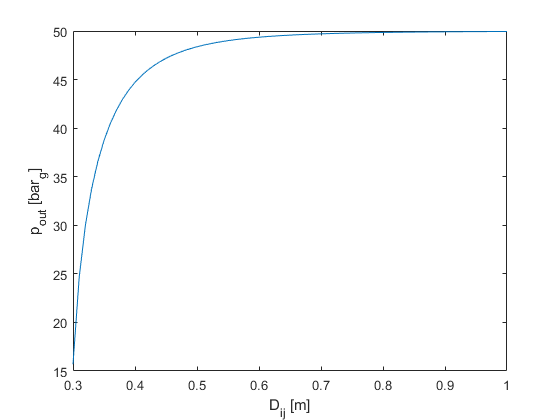

figure
plot(D_ij, p_out__barg)
xlabel('D_{ij} [m]')
ylabel('p_{out} [bar_g]')

idx = find(p_out__barg>40);
GN.pipe.D_ij = D_ij(idx(1));

% RESULT 1b
GN1b = GN;


## Aufgabe 2 - Netzanschluss für Zamonien

### Aufgabe 2.a) Leitungsausbau

Die Orte 'c' (x: 350, y: 90) und 'd' (x: 420, y: 80) sollen jeweils einen 100 MW-Gasnetzanschluss erhalten. Die Trasse von 'b' nach 'c' hat eine Länge von 50 km und die Strecke von 'c' nach 'd' hat 71 km. Beiden Pipelines haben einen Druchmesser von 300 mm und eine Rohrrauhigkeit von 50 µm.

- Welche Betriebsdrücke sind bei 'b', 'c' und 'd' bei Spitzenlast zu erwarten?

- Ergänze den folgenden Quellcode bei ???

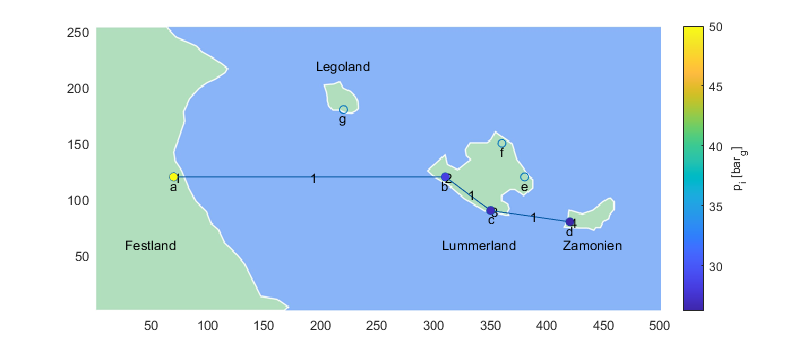

GN = GN1b;

GN.bus                  = [GN.bus;GN.bus(2,:);GN.bus(2,:)];
GN.bus.bus_ID([3,4])    = [3;4];
GN.bus.P_th_i__MW([3,4])= [100;100];
GN.bus.x_coord([3,4])   = [350;420];
GN.bus.y_coord([3,4])   = [90;80];
GN.bus.P_th_i__MW(1)    = -sum(GN.bus.P_th_i__MW(2:end));

GN.pipe                 = [GN.pipe;GN.pipe(1,:);GN.pipe(1,:)];

GN.pipe.pipe_ID(2)      = 2;
GN.pipe.from_bus_ID(2)  = 2;
GN.pipe.to_bus_ID(2)    = 3;
GN.pipe.L_ij(2)         = 50000;
GN.pipe.D_ij(2)         = 0.3;

GN.pipe.pipe_ID(3)      = 3;
GN.pipe.from_bus_ID(3)  = 3;
GN.pipe.to_bus_ID(3)    = 4;
GN.pipe.L_ij(3)         = 71000;
GN.pipe.D_ij(3)         = 0.3;

GN = check_and_init_GN(GN);
GN = rungf(GN);
h = show_Lummerland;
plot_GN_area(GN,h,[],true);

disp(['Pressure at bus 2 (b): ',num2str(GN.bus.p_i__barg(2))])

Pressure at bus 2 (b): 28.3155


disp(['Pressure at bus 3 (c): ',num2str(GN.bus.p_i__barg(3))])

Pressure at bus 3 (c): 26.8212


disp(['Pressure at bus 4 (d): ',num2str(GN.bus.p_i__barg(4))])

Pressure at bus 4 (d): 26.2451



% RESULT 2a
GN2a = GN;

### Aufgabe 2.b) Verdichter

Die Spitzenlast bei 'd' erhöht sich auf 200 MW. Der minimal zuslässige Druck bei 'd' sei 20 barg.

- Hat das bestehende Netz eine ausreichende Transportkapazität?

GN = GN2a;

GN.bus.P_th_i__MW(4) = 200;
GN.bus.P_th_i__MW(1) = -sum(GN.bus.P_th_i__MW(2:end));
GN = rungf(GN);

### Aufgabe 2.c) Verdichter

Zur Steigerung der Netztransportkapazität wird bei 'b' ein Verdichter eingebaut. Der Verdichter hat einen konstanten Ausgangsdruck von 40 barg.

- Welche Knoten ist in der neuen, hydraulisch entkoppelten Area als Slack-Knoten zu wählen?

- Kann bei 'd' der minimal zulässige Druck eingehalten werden?

- Schau dir das Netzmodell nach der Gasflussrechnung an. Was fällt dir in der Tabelle comp auf?

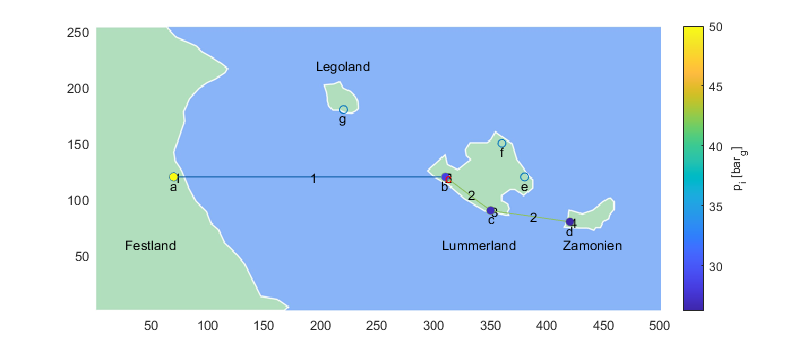

GN = GN2a;

GN.bus                  = [GN.bus;GN.bus(2,:)];
GN.bus.bus_ID(5)        = 5;
GN.bus.P_th_i__MW(5)    = 0;
GN.bus.p_i__barg(5)     = 40;
% GN.bus.x_coord(5)       = GN.bus.x_coord(end)+1;
% GN.bus.slack_bus(5)     = true;

GN.pipe.from_bus_ID(2)  = 5;

comp_ID                 = 1;
from_bus_ID             = 2;
to_bus_ID               = 5;
GN.comp                 = table(comp_ID, from_bus_ID, to_bus_ID);

GN  = check_and_init_GN(GN);
GN  = rungf(GN);
h   = show_Lummerland;
plot_GN_area(GN,h,[],true);

disp(['Pressure at bus 4: ',num2str(GN.bus.p_i__barg(4))])

Pressure at bus 4: 26.2451



% Result 2c
GN2c = GN;

## Aufgabe 3 - Gasförderung bei Zamonien

In der Nähe der Insel Zamonien wird ein Erdgasfeld mit H-Gas-Qualität entdeckt. Damit das Gas zum Festland transportiert werden kann, soll der Verdichter bei 'c' zu einer Verdichterstation mit Gasdruckreglern ausgebaut werden.

- Lass die Versorgungsaufgabe unverändert.

- Entferne zunächst den bestehend Verdichter und verbinde die Pipeline 'bc' wieder mit der Pipeline 'ab'.

- Nutze die Funktion 'add_default_comp_station', um bei 'b' eine Verdichterstation zu installieren.

- Schau dir die Topologie der Verdichterstation an.

- Führe 'rungf(GN)' aus und schau dir die Warning Message sowie die Ausgabe an.

- Führe 'rungf_time_step' aus. Welche Angaben fehlen noch?

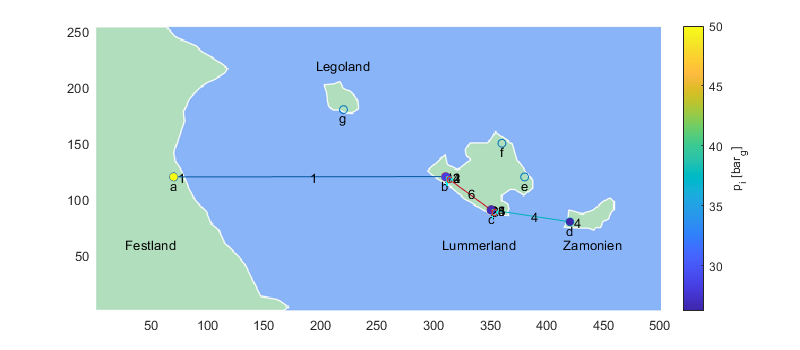

GN = GN2a;
GN = add_default_comp_station(GN,[2,3]);

GN  = check_and_init_GN(GN);
GN.bus.p_i_min__barg(:) = 20;
GN.bus.p_i_max__barg(:) = 50;

GN  = rungf_time_step(GN);

h   = show_Lummerland;
plot_GN_area(GN,h,[],true);